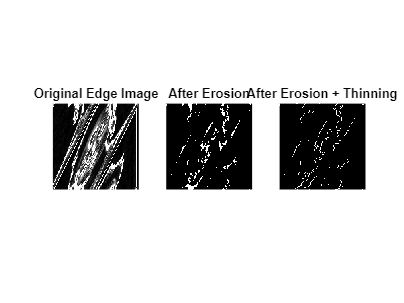

%working on the sobel


clear; close all; clc;  % Add this at the top to close all figures and clear workspace

% Read edge pixel values from CSV
data = readmatrix('sobel_output_fixed.csv', 'NumHeaderLines', 1);  % Skip header

% Check size
if numel(data) ~= 128*128
    error('Expected 128x128 = 16384 pixels, but got %d', numel(data));
end

% Reshape and transpose into 128x128 image
edge_img = reshape(data, 128, 128);

% Normalize to 0-1 range for processing
normalized_img = double(edge_img) / max(edge_img(:));

% Convert to binary (edge thresholding)
binary_edge = imbinarize(normalized_img, 0.4);  % Adjust threshold if needed

% Step 1: Erode edges slightly to thin them
se = strel('disk', 1);  % Structuring element
eroded_img = imerode(binary_edge, se);

% Step 2: Apply thinning (skeletonization)
thinned_img = bwmorph(eroded_img, 'thin', Inf);

% === Display results ===
figure;
subplot(1,3,1);
imshow(normalized_img);
title('Original Edge Image');

subplot(1,3,2);
imshow(eroded_img);
title('After Erosion');

subplot(1,3,3);
imshow(thinned_img);
title('After Erosion + Thinning');


% === Save results ===
imwrite(normalized_img, 'edge_output_normalized.png');
imwrite(eroded_img, 'edge_output_eroded.png');
imwrite(thinned_img, 'edge_output_thinned.png');


